# Setup Files

## Input Parameters

Airfoil profile

AirfoilName = inputdlg("What is the name of the Airfoil: ", "s"); %NACA 4412
AirfoilFileName = input("What is the File Name for the Coordinates: ", "s") %NACA 4412C.txt"

AirfoilFileName = 'NACA 4412.txt'

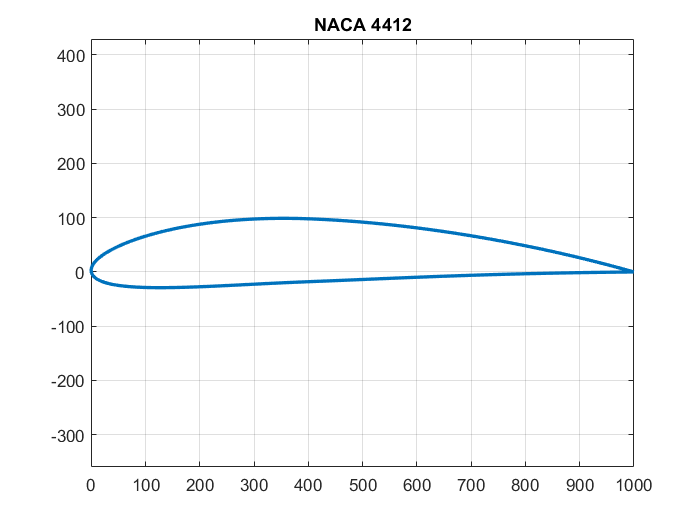

AirfoilXY = load(AirfoilFileName); %Load Airfoil Co-ordinates
XPos = AirfoilXY(:, 3); %Xposition
YPos = AirfoilXY(:, 4); %YPosition
plot(XPos, YPos, "LineWidth", 2) %Plot Airfoil
title(AirfoilName)
grid on
axis equal
exportgraphics(gcf,'Airfoil-Profile.png') %Export airfoil profile

AOA = input("Angle of Attack (degrees) [row matrix]: ") %AOA

AOA =      0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30


recLength = ones(1,length(AOA))*20 %Domain Length

recLength =     20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20


recHeight = ones(1,length(AOA))*10 %Domain Height

recHeight =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10


Vin = input("What is your inlet velocity: "); %Inlet velocity
Vin = ones(1,length(AOA))*Vin %Arr inlet Velocity

Vin =     60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60


values = [recLength' recHeight' AOA' Vin'] %Input Values

values =     20    10     0    60
    20    10     2    60
    20    10     4    60
    20    10     6    60
    20    10     8    60
    20    10    10    60
    20    10    12    60
    20    10    14    60
    20    10    16    60
    20    10    18    60


headers = {'Domain_Length (m)', 'Domain_Height (m)', 'Angle of Attack (deg)','Vin (m/s)'} %Excel header name

headers = 1×4 cell array
    {'Domain_Length (m)'}    {'Domain_Height (m)'}    {'Angle of Attack (deg)'}    {'Vin (m/s)'}


xlswrite("Input_Data.xlsx",headers, 1, 'A1'); 
xlswrite("Input_Data.xlsx", values, 1, 'A2');

## Read Results

while (isfile("Results.csv") == 0) %Check if ANSYS has finished Simulation
    
end
result = xlsread("Results.csv");
AOA = AOA';
PLiftF = result(:,8); %Lift Force
PDragF = result(:,7); %Drag Force
PLiftC = result(:,9); %Lift Coefjm 
PDragC = result(:,10); %Drag Coef

## Interpret results

Forces

%Minmium Lift and Drag Force
[minLift, idxMinLift] = min(PLiftF);
[minDrag, idxMinDrag] = min(PDragF);
%Minimum Positions
MinLiftPos = [AOA(idxMinLift), minLift];
MinDragPos = [AOA(idxMinDrag), minDrag];
%Maximum Lift and Drag Force
[maxLift, idxMaxLift] = max(PLiftF);
[maxDrag, idxMaxDrag] = max(PDragF);
%Maximum Positions
MaxLiftPos = [AOA(idxMaxLift), maxLift];
MaxDragPos = [AOA(idxMaxDrag), maxDrag];

Coefficients

%Minmium LiftC and Drag Coefficients
[minLiftC, idxMinLiftC] = min(PLiftC);
[minDragC, idxMinDragC] = min(PDragC);
%Minimum Positions
MinLiftCPos = [AOA(idxMinLiftC), minLiftC];
MinDragCPos = [AOA(idxMinDragC), minDragC];
%Maximum Lift and Drag Coefficients
[maxLiftC, idxMaxLiftC] = max(PLiftC);
[maxDragC, idxMaxDragC] = max(PDragC);
%Maximum Positions
MaxLiftCPos = [AOA(idxMaxLiftC), maxLiftC];
MaxDragCPos = [AOA(idxMaxDragC), maxDragC];

## Plots

Lift Plot

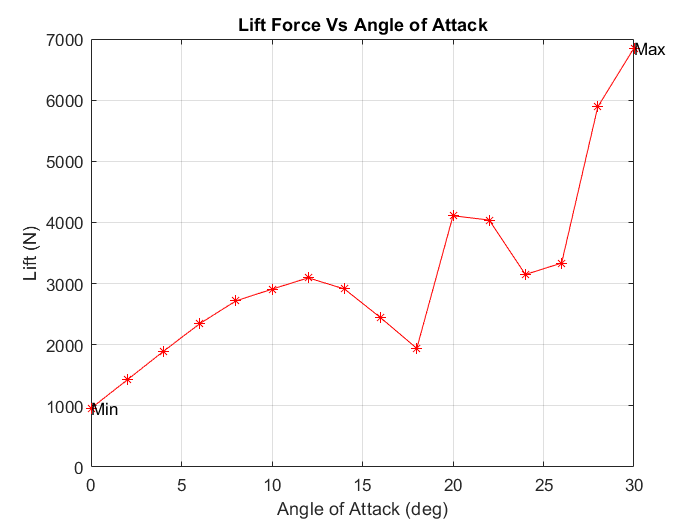

plot(AOA,PLiftF, 'r-*')
title("Lift Force Vs Angle of Attack")
text(MinLiftPos(1), MinLiftPos(2), "Min")
text(MaxLiftPos(1), MaxLiftPos(2), "Max")
xlabel("Angle of Attack (deg)")
ylabel("Lift (N)")
grid on
exportgraphics(gcf,'Lift Vs AOA.png')

Drag Plot

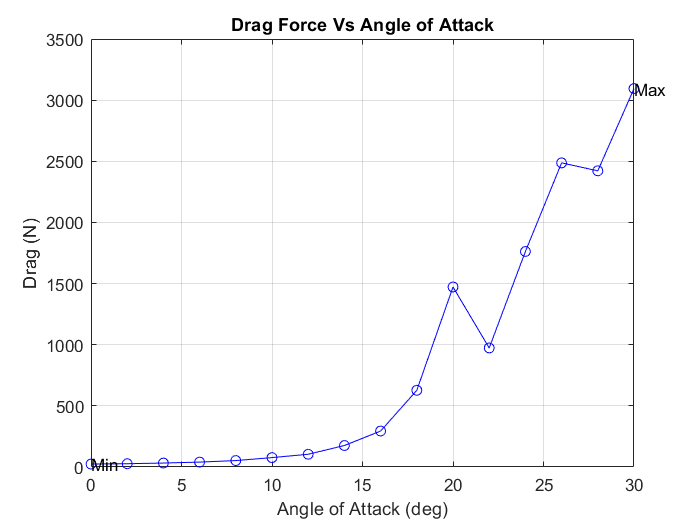

plot(AOA,PDragF, 'b-o')
title("Drag Force Vs Angle of Attack")
text(MinDragPos(1), MinDragPos(2), "Min")
text(MaxDragPos(1), MaxDragPos(2), "Max")
xlabel("Angle of Attack (deg)")
ylabel("Drag (N)")
grid on
exportgraphics(gcf,'Drag Vs AOA.png')

Coefficient of Lift

LM = islocalmin(PLiftC)

LM = 16×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1


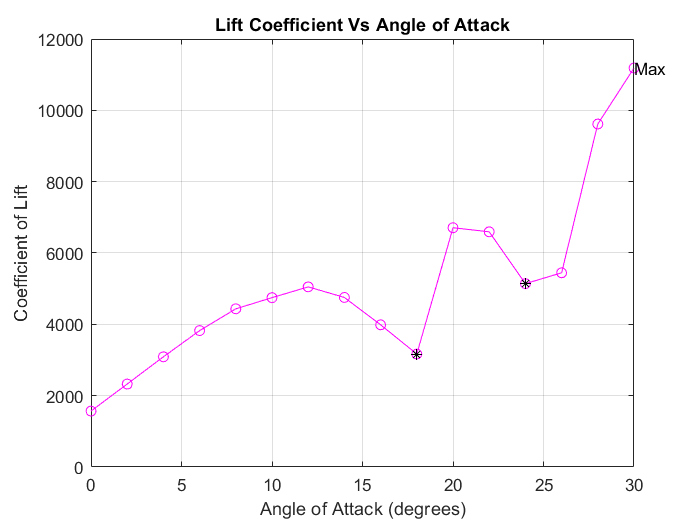

plot(AOA, PLiftC, 'm-o', AOA(LM), PLiftC(LM), 'k*')
title("Lift Coefficient Vs Angle of Attack")
xlabel("Angle of Attack (degrees)")
ylabel("Coefficient of Lift")
text(MaxLiftCPos(1), MaxLiftCPos(2), "Max")
xline(MaxLiftCPos(1))
grid on
exportgraphics(gcf,'CoeffL Vs AOA.png')

Lift-Drag Ratio

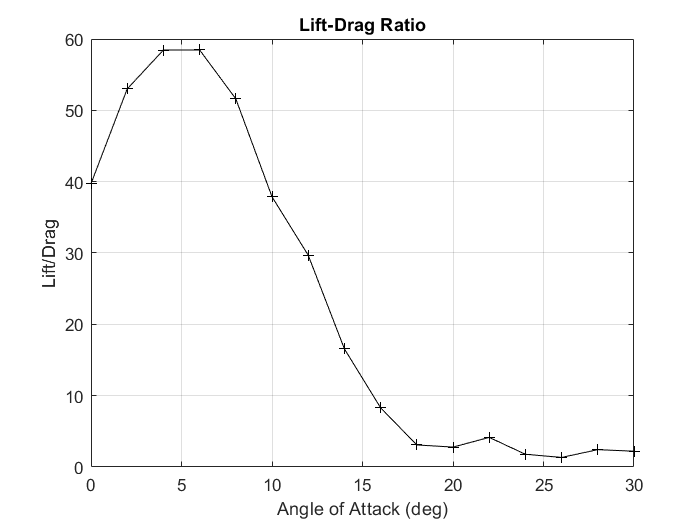

ldr = PLiftF./PDragF;
plot(AOA, ldr, 'k-+')
title("Lift-Drag Ratio")
xlabel("Angle of Attack (deg)")
ylabel("Lift/Drag")
grid on
exportgraphics(gcf,'Lift-Drag Ratio.png')

Critical Point

%% Failed Approach
% dlda = diff(PLiftC); %Derivative of Lift Coefficient
% dldaBin = dlda < 0;
% i = 1;
% %Search for a change in sign
% while i < length(dldaBin)
%     intervalAOA = AOA(i-2:i+2)
%     if ((dldaBin(i) == 1) && (dldaBin(i+1) == 0))
%         idxCritical = i+1;
%         break
%     else 
%         i = i+1;
%     end
% end
% AOACr = AOA(idxCritical) %Critical angle of attack

%Successful Approach
PAOAcr = AOA(find(LM==1))

PAOAcr =     18
    24


AOACr = min(PAOAcr((PAOAcr >= 14) & (PAOAcr <= 19)))

AOACr = 18

## Summary

fid = fopen('summary.txt', 'wt+');
AOA_s = sprintf('%0.3f ', AOA');
summary = "Airfoil: "+ AirfoilName ...
    + "\n\nVelocity (m/s): " + max(Vin) + "\tAOA's (deg): " +  AOA_s + "\n\nMax Lift Force (N): " + maxLift + "\tAOA: " + AOA(idxMaxLift) +...
    "\nMin Lift Force (N): " + minLift + "\tAOA: " + AOA(idxMinLift) + "\nMax Drag Force (N): " + maxDrag + "\tAOA: " + AOA(idxMaxDrag) + "\nMin Drag Force (N): " + minDrag + "\tAOA: " + AOA(idxMinDrag)+ "\n\nCritical Angle: " + AOACr + " deg" ...
    + "\n\nConclusion: Stall occurs at " + AOACr + " degrees" + "\n\nOther potential critical angles (deg): "+ sprintf('%0.0f ', PAOAcr') +"\n\n*See report for more details";
fprintf(fid, summary);
fclose(fid);